% Dodaj bieżący folder do ścieżki MATLAB
addpath(pwd);

% Wspólne parametry dla wszystkich symulacji
T_total = 800000;                  % Total simulation time (ms)
longDRX_cycle = 512;              % Long DRX cycle (ms)
inactivity_timer = 100;           % Inactivity timer (ms)
on_duration = 50;                 % On duration (ms)
packet_reception_time = 10;       % Time to receive a packet (ms)
frequency_of_incoming_packet = [250, 500, 1000, 2000, 5000]; % Packet frequencies (ms)

% Parametry specyficzne dla WUS i C-DRX
ps_Offset = 3;                  % ps-Offset dla WUS (ms)
minTimeGap = 0.5;                   % minTimeGap dla WUS (ms)
shortDRX_cycle = 128;             % Short DRX cycle dla C-DRX (ms)
shortCycleTimer = 5;              % Short cycle timer dla C-DRX

% Inicjalizacja wyników
num_freqs = length(frequency_of_incoming_packet);
energy_results = zeros(3, num_freqs); % 3 tryby DRX
delay_results = zeros(3, num_freqs);

% Przeprowadzenie symulacji dla każdej częstotliwości pakietów
for i = 1:num_freqs
    freq = frequency_of_incoming_packet(i);
    
    % 1. Zwykły DRX
    [energy_results(1,i), delay_results(1,i)] = drx_script(...
        T_total, longDRX_cycle, inactivity_timer, on_duration, freq, packet_reception_time);
    
    % 2. DRX z WUS
    [energy_results(2,i), delay_results(2,i)] = wus_drx_script(...
        T_total, longDRX_cycle, inactivity_timer, on_duration, freq, packet_reception_time, ...
        ps_Offset, minTimeGap);
    
    % 3. C-DRX
    [energy_results(3,i), delay_results(3,i)] = c_drx_script(...
        T_total, longDRX_cycle, inactivity_timer, on_duration, freq, packet_reception_time, ...
        shortDRX_cycle, shortCycleTimer);
end


=== Starting DRX Simulation ===
Total simulation time: 800000 ms
Long DRX cycle: 512 ms
Inactivity timer: 100 ms
On duration: 50 ms
Packet frequency: 250 ms
Packet reception time: 10 ms

Initial state: inactivity_timer
INACTIVITY_TIMER: 100 ms (Energy: 10000.0 mJ)
! STATE ON time counter: 100)
-> State change: INACTIVITY_TIMER -> SLEEP (Cycle #1)
DEEP_SLEEP: 412 ms (Energy: 651.3 mJ)
[Energy update] Total: 10651.3 mJ | Saved: 0.0%
-> State change: SLEEP -> ON_DURATION

[Packet #3 arrived during SLEEP at last cycle at 250 ms]

[Processing 2 pending packets that arrived during SLEEP]
-> Processing packet arrived at 250 ms (delay: 262 ms)
-> Processing packet arrived at 500 ms (delay: 12 ms)
[Energy after processing 2 packets] Total: 19651.3 mJ | Saved: 0.0%
-> State change: ON_DURATION -> INACTIVITY_TIMER (Cycle #2)
INACTIVITY_TIMER: 100 ms (Energy: 10000.0 mJ)
! STATE ON time counter: 150)
-> State change: INACTIVITY_TIMER -> SLEEP (Cycle #2)
DEEP_SLEEP: 362 ms (Energy: 601.3 mJ)
[Ener


=== Starting DRX Simulation ===
Total simulation time: 800000 ms
Long DRX cycle: 512 ms
Inactivity timer: 100 ms
On duration: 50 ms
Packet frequency: 250 ms
Packet reception time: 10 ms
ps-Offset time: 3 ms
minTimeGap time: 5.000000e-01 ms

Initial state: inactivity_timer
INACTIVITY_TIMER: 100 ms (Energy: 10000.0 mJ)
! STATE ON time counter: 100)
-> State change: INACTIVITY_TIMER -> SLEEP (Cycle #1)
DEEP_SLEEP: 409 ms (Energy: 648.3 mJ)
[Energy update] Total: 10648.3 mJ | Saved: 0.0%
-> State change: SLEEP -> wus_signal
WAKE UP SIGNAL : 1
[Packet #3 arrived during SLEEP at last cycle at 250 ms]
-> State change: WAKE_UP SIGNAL -> ON DURATION (Cycle #2)
[Energy after WUS] Total: 10898.3 mJ | Saved: 0.0%
LIGHT_SLEEP: 5.000000e-01 ms (Energy: 20.6 mJ)
[Energy update] Total: 10919.0 mJ | Saved: 0.0%
-> State change: SLEEP -> on_duration

[Packet #3 arrived during SLEEP at last cycle at 250 ms]

[Processing 2 pending packets that arrived during SLEEP]
-> Processing packet arrived at 250 ms 


=== Starting C-DRX Simulation ===
Total simulation time: 800000 ms
Long DRX cycle: 512 ms
Short DRX cycle: 128 ms
Short DRX cycle timer: 5
Inactivity timer: 100 ms
On duration: 50 ms
Packet frequency: 250 ms
Packet reception time: 10 ms

Initial state: inactivity_timer
INACTIVITY_TIMER: 100 ms (Energy: 10000.0 mJ)
! STATE ON time counter: 100)
-> State change: INACTIVITY_TIMER -> SLEEP (Cycle #1)
DEEP_SLEEP: 28 ms (Energy: 267.3 mJ)
[Energy update] Total: 10267.3 mJ | Saved: 0.0%
short_DRX_counter: 128
Short DRX Timer short cycle zostało: 4
-> State change: SLEEP -> ON_DURATION
! STATE ON time counter: 50
ON_DURATION: 50 ms (Energy: 5000.0 mJ)
-> State change: ON_DURATION -> SLEEP (Cycle #2)
DEEP_SLEEP: 78 ms (Energy: 317.3 mJ)
[Energy update] Total: 15584.6 mJ | Saved: 0.0%
short_DRX_counter: 256
Short DRX Timer short cycle zostało: 3
-> State change: SLEEP -> ON_DURATION

[Packet #2 arrived during SLEEP at last cycle at 250 ms]

[Processing 1 pending packets that arrived during SLEE


=== Starting DRX Simulation ===
Total simulation time: 800000 ms
Long DRX cycle: 512 ms
Inactivity timer: 100 ms
On duration: 50 ms
Packet frequency: 500 ms
Packet reception time: 10 ms

Initial state: inactivity_timer
INACTIVITY_TIMER: 100 ms (Energy: 10000.0 mJ)
! STATE ON time counter: 100)
-> State change: INACTIVITY_TIMER -> SLEEP (Cycle #1)
DEEP_SLEEP: 412 ms (Energy: 651.3 mJ)
[Energy update] Total: 10651.3 mJ | Saved: 0.0%
-> State change: SLEEP -> ON_DURATION

[Packet #2 arrived during SLEEP at last cycle at 500 ms]

[Processing 1 pending packets that arrived during SLEEP]
-> Processing packet arrived at 500 ms (delay: 12 ms)
[Energy after processing 1 packets] Total: 17651.3 mJ | Saved: 0.0%
-> State change: ON_DURATION -> INACTIVITY_TIMER (Cycle #2)
INACTIVITY_TIMER: 100 ms (Energy: 10000.0 mJ)
! STATE ON time counter: 150)
-> State change: INACTIVITY_TIMER -> SLEEP (Cycle #2)
DEEP_SLEEP: 362 ms (Energy: 601.3 mJ)
[Energy update] Total: 28252.6 mJ | Saved: 0.0%
-> State cha


=== Starting DRX Simulation ===
Total simulation time: 800000 ms
Long DRX cycle: 512 ms
Inactivity timer: 100 ms
On duration: 50 ms
Packet frequency: 500 ms
Packet reception time: 10 ms
ps-Offset time: 3 ms
minTimeGap time: 5.000000e-01 ms

Initial state: inactivity_timer
INACTIVITY_TIMER: 100 ms (Energy: 10000.0 mJ)
! STATE ON time counter: 100)
-> State change: INACTIVITY_TIMER -> SLEEP (Cycle #1)
DEEP_SLEEP: 409 ms (Energy: 648.3 mJ)
[Energy update] Total: 10648.3 mJ | Saved: 0.0%
-> State change: SLEEP -> wus_signal
WAKE UP SIGNAL : 1
[Packet #2 arrived during SLEEP at last cycle at 500 ms]
-> State change: WAKE_UP SIGNAL -> ON DURATION (Cycle #2)
[Energy after WUS] Total: 10898.3 mJ | Saved: 0.0%
LIGHT_SLEEP: 5.000000e-01 ms (Energy: 20.6 mJ)
[Energy update] Total: 10919.0 mJ | Saved: 0.0%
-> State change: SLEEP -> on_duration

[Packet #2 arrived during SLEEP at last cycle at 500 ms]

[Processing 1 pending packets that arrived during SLEEP]
-> Processing packet arrived at 500 ms 


=== Starting C-DRX Simulation ===
Total simulation time: 800000 ms
Long DRX cycle: 512 ms
Short DRX cycle: 128 ms
Short DRX cycle timer: 5
Inactivity timer: 100 ms
On duration: 50 ms
Packet frequency: 500 ms
Packet reception time: 10 ms

Initial state: inactivity_timer
INACTIVITY_TIMER: 100 ms (Energy: 10000.0 mJ)
! STATE ON time counter: 100)
-> State change: INACTIVITY_TIMER -> SLEEP (Cycle #1)
DEEP_SLEEP: 28 ms (Energy: 267.3 mJ)
[Energy update] Total: 10267.3 mJ | Saved: 0.0%
short_DRX_counter: 128
Short DRX Timer short cycle zostało: 4
-> State change: SLEEP -> ON_DURATION
! STATE ON time counter: 50
ON_DURATION: 50 ms (Energy: 5000.0 mJ)
-> State change: ON_DURATION -> SLEEP (Cycle #2)
DEEP_SLEEP: 78 ms (Energy: 317.3 mJ)
[Energy update] Total: 15584.6 mJ | Saved: 0.0%
short_DRX_counter: 256
Short DRX Timer short cycle zostało: 3
-> State change: SLEEP -> ON_DURATION
! STATE ON time counter: 50
ON_DURATION: 50 ms (Energy: 5000.0 mJ)
-> State change: ON_DURATION -> SLEEP (Cycle #


=== Starting DRX Simulation ===
Total simulation time: 800000 ms
Long DRX cycle: 512 ms
Inactivity timer: 100 ms
On duration: 50 ms
Packet frequency: 1000 ms
Packet reception time: 10 ms

Initial state: inactivity_timer
INACTIVITY_TIMER: 100 ms (Energy: 10000.0 mJ)
! STATE ON time counter: 100)
-> State change: INACTIVITY_TIMER -> SLEEP (Cycle #1)
DEEP_SLEEP: 412 ms (Energy: 651.3 mJ)
[Energy update] Total: 10651.3 mJ | Saved: 0.0%
-> State change: SLEEP -> ON_DURATION
! STATE ON time counter: 50
ON_DURATION: 50 ms (Energy: 5000.0 mJ)
-> State change: ON_DURATION -> SLEEP (Cycle #2)
DEEP_SLEEP: 462 ms (Energy: 701.3 mJ)
[Energy update] Total: 16352.6 mJ | Saved: 0.0%
-> State change: SLEEP -> ON_DURATION

[Packet #2 arrived during SLEEP at last cycle at 1000 ms]

[Processing 1 pending packets that arrived during SLEEP]
-> Processing packet arrived at 1000 ms (delay: 24 ms)
[Energy after processing 1 packets] Total: 23352.6 mJ | Saved: 0.0%
-> State change: ON_DURATION -> INACTIVITY_TI


=== Starting DRX Simulation ===
Total simulation time: 800000 ms
Long DRX cycle: 512 ms
Inactivity timer: 100 ms
On duration: 50 ms
Packet frequency: 1000 ms
Packet reception time: 10 ms
ps-Offset time: 3 ms
minTimeGap time: 5.000000e-01 ms

Initial state: inactivity_timer
INACTIVITY_TIMER: 100 ms (Energy: 10000.0 mJ)
! STATE ON time counter: 100)
-> State change: INACTIVITY_TIMER -> SLEEP (Cycle #1)
DEEP_SLEEP: 409 ms (Energy: 648.3 mJ)
[Energy update] Total: 10648.3 mJ | Saved: 0.0%
-> State change: SLEEP -> wus_signal
WAKE UP SIGNAL : 0 - no packet arrived 
-> State change: WAKE_UP SIGNAL -> SLEEP (Cycle #2)
[Energy after WUS] Total: 10898.3 mJ | Saved: 0.0%
DEEP_SLEEP: 5.095000e+02 ms (Energy: 748.8 mJ)
[Energy update] Total: 11647.1 mJ | Saved: 0.0%
-> State change: SLEEP -> wus_signal
WAKE UP SIGNAL : 1
[Packet #2 arrived during SLEEP at last cycle at 1000 ms]
-> State change: WAKE_UP SIGNAL -> ON DURATION (Cycle #3)
[Energy after WUS] Total: 11897.1 mJ | Saved: 0.0%
LIGHT_SLEEP


=== Starting C-DRX Simulation ===
Total simulation time: 800000 ms
Long DRX cycle: 512 ms
Short DRX cycle: 128 ms
Short DRX cycle timer: 5
Inactivity timer: 100 ms
On duration: 50 ms
Packet frequency: 1000 ms
Packet reception time: 10 ms

Initial state: inactivity_timer
INACTIVITY_TIMER: 100 ms (Energy: 10000.0 mJ)
! STATE ON time counter: 100)
-> State change: INACTIVITY_TIMER -> SLEEP (Cycle #1)
DEEP_SLEEP: 28 ms (Energy: 267.3 mJ)
[Energy update] Total: 10267.3 mJ | Saved: 0.0%
short_DRX_counter: 128
Short DRX Timer short cycle zostało: 4
-> State change: SLEEP -> ON_DURATION
! STATE ON time counter: 50
ON_DURATION: 50 ms (Energy: 5000.0 mJ)
-> State change: ON_DURATION -> SLEEP (Cycle #2)
DEEP_SLEEP: 78 ms (Energy: 317.3 mJ)
[Energy update] Total: 15584.6 mJ | Saved: 0.0%
short_DRX_counter: 256
Short DRX Timer short cycle zostało: 3
-> State change: SLEEP -> ON_DURATION
! STATE ON time counter: 50
ON_DURATION: 50 ms (Energy: 5000.0 mJ)
-> State change: ON_DURATION -> SLEEP (Cycle 


=== Starting DRX Simulation ===
Total simulation time: 800000 ms
Long DRX cycle: 512 ms
Inactivity timer: 100 ms
On duration: 50 ms
Packet frequency: 2000 ms
Packet reception time: 10 ms

Initial state: inactivity_timer
INACTIVITY_TIMER: 100 ms (Energy: 10000.0 mJ)
! STATE ON time counter: 100)
-> State change: INACTIVITY_TIMER -> SLEEP (Cycle #1)
DEEP_SLEEP: 412 ms (Energy: 651.3 mJ)
[Energy update] Total: 10651.3 mJ | Saved: 0.0%
-> State change: SLEEP -> ON_DURATION
! STATE ON time counter: 50
ON_DURATION: 50 ms (Energy: 5000.0 mJ)
-> State change: ON_DURATION -> SLEEP (Cycle #2)
DEEP_SLEEP: 462 ms (Energy: 701.3 mJ)
[Energy update] Total: 16352.6 mJ | Saved: 0.0%
-> State change: SLEEP -> ON_DURATION
! STATE ON time counter: 50
ON_DURATION: 50 ms (Energy: 5000.0 mJ)
-> State change: ON_DURATION -> SLEEP (Cycle #3)
DEEP_SLEEP: 462 ms (Energy: 701.3 mJ)
[Energy update] Total: 22054.0 mJ | Saved: 0.0%
-> State change: SLEEP -> ON_DURATION
! STATE ON time counter: 50
ON_DURATION: 50 m


=== Starting DRX Simulation ===
Total simulation time: 800000 ms
Long DRX cycle: 512 ms
Inactivity timer: 100 ms
On duration: 50 ms
Packet frequency: 2000 ms
Packet reception time: 10 ms
ps-Offset time: 3 ms
minTimeGap time: 5.000000e-01 ms

Initial state: inactivity_timer
INACTIVITY_TIMER: 100 ms (Energy: 10000.0 mJ)
! STATE ON time counter: 100)
-> State change: INACTIVITY_TIMER -> SLEEP (Cycle #1)
DEEP_SLEEP: 409 ms (Energy: 648.3 mJ)
[Energy update] Total: 10648.3 mJ | Saved: 0.0%
-> State change: SLEEP -> wus_signal
WAKE UP SIGNAL : 0 - no packet arrived 
-> State change: WAKE_UP SIGNAL -> SLEEP (Cycle #2)
[Energy after WUS] Total: 10898.3 mJ | Saved: 0.0%
DEEP_SLEEP: 5.095000e+02 ms (Energy: 748.8 mJ)
[Energy update] Total: 11647.1 mJ | Saved: 0.0%
-> State change: SLEEP -> wus_signal
WAKE UP SIGNAL : 0 - no packet arrived 
-> State change: WAKE_UP SIGNAL -> SLEEP (Cycle #3)
[Energy after WUS] Total: 11897.1 mJ | Saved: 0.0%
DEEP_SLEEP: 5.095000e+02 ms (Energy: 748.8 mJ)
[Energy


=== Starting C-DRX Simulation ===
Total simulation time: 800000 ms
Long DRX cycle: 512 ms
Short DRX cycle: 128 ms
Short DRX cycle timer: 5
Inactivity timer: 100 ms
On duration: 50 ms
Packet frequency: 2000 ms
Packet reception time: 10 ms

Initial state: inactivity_timer
INACTIVITY_TIMER: 100 ms (Energy: 10000.0 mJ)
! STATE ON time counter: 100)
-> State change: INACTIVITY_TIMER -> SLEEP (Cycle #1)
DEEP_SLEEP: 28 ms (Energy: 267.3 mJ)
[Energy update] Total: 10267.3 mJ | Saved: 0.0%
short_DRX_counter: 128
Short DRX Timer short cycle zostało: 4
-> State change: SLEEP -> ON_DURATION
! STATE ON time counter: 50
ON_DURATION: 50 ms (Energy: 5000.0 mJ)
-> State change: ON_DURATION -> SLEEP (Cycle #2)
DEEP_SLEEP: 78 ms (Energy: 317.3 mJ)
[Energy update] Total: 15584.6 mJ | Saved: 0.0%
short_DRX_counter: 256
Short DRX Timer short cycle zostało: 3
-> State change: SLEEP -> ON_DURATION
! STATE ON time counter: 50
ON_DURATION: 50 ms (Energy: 5000.0 mJ)
-> State change: ON_DURATION -> SLEEP (Cycle 


=== Starting DRX Simulation ===
Total simulation time: 800000 ms
Long DRX cycle: 512 ms
Inactivity timer: 100 ms
On duration: 50 ms
Packet frequency: 5000 ms
Packet reception time: 10 ms

Initial state: inactivity_timer
INACTIVITY_TIMER: 100 ms (Energy: 10000.0 mJ)
! STATE ON time counter: 100)
-> State change: INACTIVITY_TIMER -> SLEEP (Cycle #1)
DEEP_SLEEP: 412 ms (Energy: 651.3 mJ)
[Energy update] Total: 10651.3 mJ | Saved: 0.0%
-> State change: SLEEP -> ON_DURATION
! STATE ON time counter: 50
ON_DURATION: 50 ms (Energy: 5000.0 mJ)
-> State change: ON_DURATION -> SLEEP (Cycle #2)
DEEP_SLEEP: 462 ms (Energy: 701.3 mJ)
[Energy update] Total: 16352.6 mJ | Saved: 0.0%
-> State change: SLEEP -> ON_DURATION
! STATE ON time counter: 50
ON_DURATION: 50 ms (Energy: 5000.0 mJ)
-> State change: ON_DURATION -> SLEEP (Cycle #3)
DEEP_SLEEP: 462 ms (Energy: 701.3 mJ)
[Energy update] Total: 22054.0 mJ | Saved: 0.0%
-> State change: SLEEP -> ON_DURATION
! STATE ON time counter: 50
ON_DURATION: 50 m


=== Starting DRX Simulation ===
Total simulation time: 800000 ms
Long DRX cycle: 512 ms
Inactivity timer: 100 ms
On duration: 50 ms
Packet frequency: 5000 ms
Packet reception time: 10 ms
ps-Offset time: 3 ms
minTimeGap time: 5.000000e-01 ms

Initial state: inactivity_timer
INACTIVITY_TIMER: 100 ms (Energy: 10000.0 mJ)
! STATE ON time counter: 100)
-> State change: INACTIVITY_TIMER -> SLEEP (Cycle #1)
DEEP_SLEEP: 409 ms (Energy: 648.3 mJ)
[Energy update] Total: 10648.3 mJ | Saved: 0.0%
-> State change: SLEEP -> wus_signal
WAKE UP SIGNAL : 0 - no packet arrived 
-> State change: WAKE_UP SIGNAL -> SLEEP (Cycle #2)
[Energy after WUS] Total: 10898.3 mJ | Saved: 0.0%
DEEP_SLEEP: 5.095000e+02 ms (Energy: 748.8 mJ)
[Energy update] Total: 11647.1 mJ | Saved: 0.0%
-> State change: SLEEP -> wus_signal
WAKE UP SIGNAL : 0 - no packet arrived 
-> State change: WAKE_UP SIGNAL -> SLEEP (Cycle #3)
[Energy after WUS] Total: 11897.1 mJ | Saved: 0.0%
DEEP_SLEEP: 5.095000e+02 ms (Energy: 748.8 mJ)
[Energy


=== Starting C-DRX Simulation ===
Total simulation time: 800000 ms
Long DRX cycle: 512 ms
Short DRX cycle: 128 ms
Short DRX cycle timer: 5
Inactivity timer: 100 ms
On duration: 50 ms
Packet frequency: 5000 ms
Packet reception time: 10 ms

Initial state: inactivity_timer
INACTIVITY_TIMER: 100 ms (Energy: 10000.0 mJ)
! STATE ON time counter: 100)
-> State change: INACTIVITY_TIMER -> SLEEP (Cycle #1)
DEEP_SLEEP: 28 ms (Energy: 267.3 mJ)
[Energy update] Total: 10267.3 mJ | Saved: 0.0%
short_DRX_counter: 128
Short DRX Timer short cycle zostało: 4
-> State change: SLEEP -> ON_DURATION
! STATE ON time counter: 50
ON_DURATION: 50 ms (Energy: 5000.0 mJ)
-> State change: ON_DURATION -> SLEEP (Cycle #2)
DEEP_SLEEP: 78 ms (Energy: 317.3 mJ)
[Energy update] Total: 15584.6 mJ | Saved: 0.0%
short_DRX_counter: 256
Short DRX Timer short cycle zostało: 3
-> State change: SLEEP -> ON_DURATION
! STATE ON time counter: 50
ON_DURATION: 50 ms (Energy: 5000.0 mJ)
-> State change: ON_DURATION -> SLEEP (Cycle 

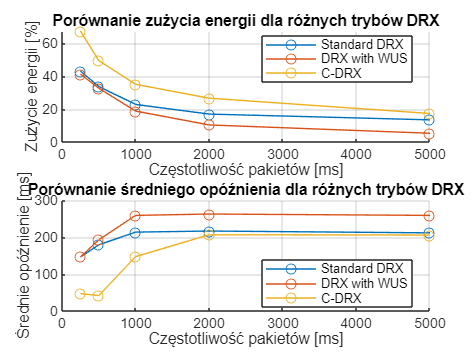


% Wykresy porównawcze
figure;

% Wykres energii
subplot(2,1,1);
hold on;
plot(frequency_of_incoming_packet, energy_results(1,:), '-o', 'DisplayName', 'Standard DRX');
plot(frequency_of_incoming_packet, energy_results(2,:), '-o', 'DisplayName', 'DRX with WUS');
plot(frequency_of_incoming_packet, energy_results(3,:), '-o', 'DisplayName', 'C-DRX');
hold off;
title('Porównanie zużycia energii dla różnych trybów DRX');
xlabel('Częstotliwość pakietów [ms]');
ylabel('Zużycie energii [%]');
legend('Location', 'best');
grid on;

% Wykres opóźnień
subplot(2,1,2);
hold on;
plot(frequency_of_incoming_packet, delay_results(1,:), '-o', 'DisplayName', 'Standard DRX');
plot(frequency_of_incoming_packet, delay_results(2,:), '-o', 'DisplayName', 'DRX with WUS');
plot(frequency_of_incoming_packet, delay_results(3,:), '-o', 'DisplayName', 'C-DRX');
hold off;
title('Porównanie średniego opóźnienia dla różnych trybów DRX');
xlabel('Częstotliwość pakietów [ms]');
ylabel('Średnie opóźnienie [ms]');
legend('Location', 'best');
grid on;

% Dostosowanie wyglądu
set(gcf, 'Position', [100 100 800 600]);